# Train Biped Robot to Walk Using Reinforcement Learning Agents

This example shows how to train a biped robot to walk using either a deep deterministic policy gradient (DDPG) agent or a twin-delayed deep deterministic policy gradient (TD3) agent. In the example, you also compare the performance of these trained agents. The robot in this example is modeled in Simscape™ Multibody™. For more information on these agents, see [Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_66c8fe60-f58e-4bdb-904a-21d442f0a879) and [Twin-Delayed Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_3a8116dc-284e-4d85-a31c-0921ec03916e).

For the purpose of comparison in this example, this example trains both agents on the biped robot environment with the same model parameters. The example also configures the agents to have the following settings in common. 

- Initial condition strategy of the biped robot

- Network structure of actor and critic, inspired by [1]

- Options for actor and critic representations

- Training options (sample time, discount factor, mini-batch size, experience buffer length, exploration noise)

## Biped Robot Model

The reinforcement learning environment for this example is a biped robot. The training goal is to make the robot walk in a straight line using minimal control effort.

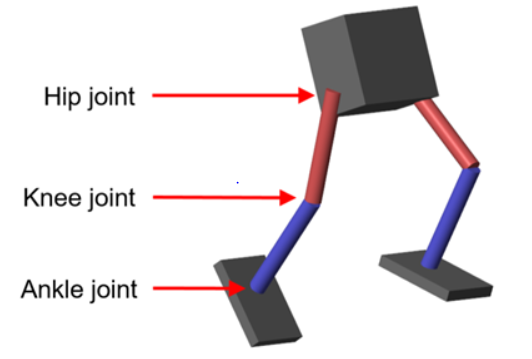

Load the parameters of the model into the MATLAB® workspace.

robotParametersRL

Open the Simulink® model.

mdl = "rlWalkingBipedRobot";
open_system(mdl)

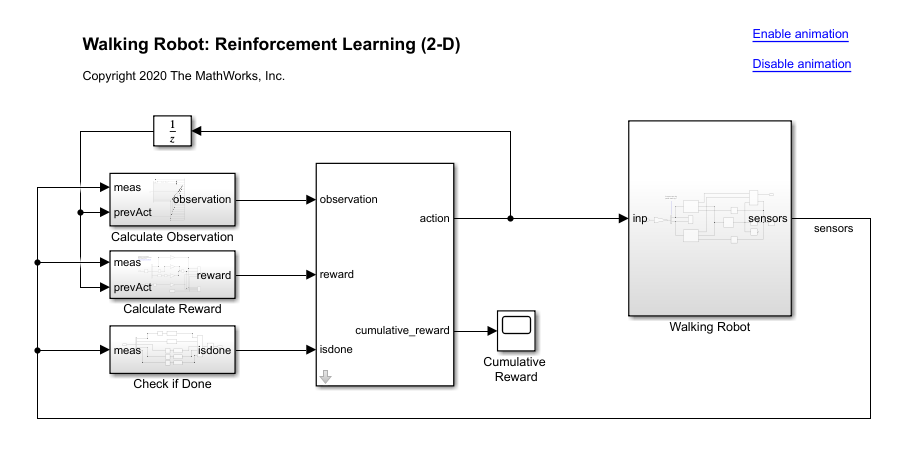

The robot is modeled using Simscape Multibody.

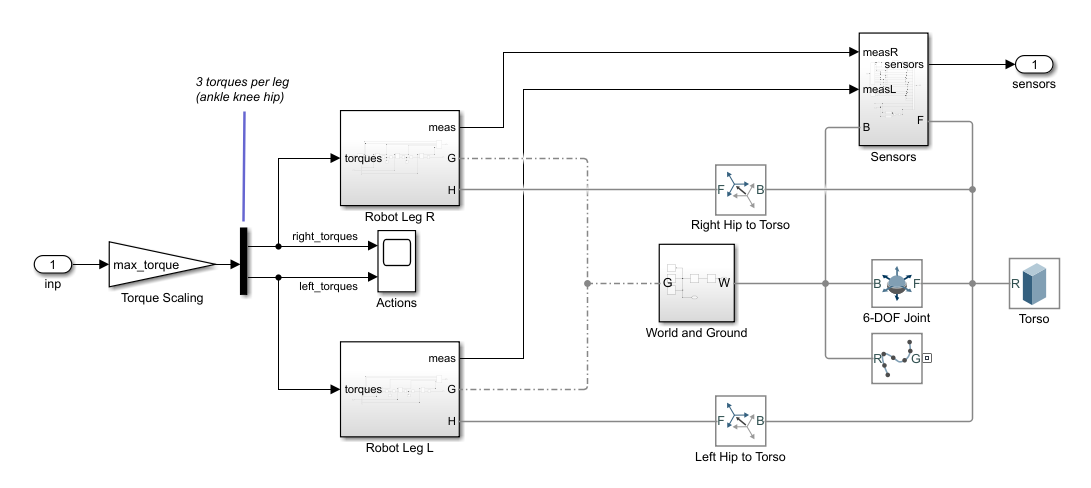

For this model:

- In the neutral 0 rad position, both of the legs are straight and the ankles are flat.

- The foot contact is modeled using the [Spatial Contact Force](docid:sm_ref#mw_42c86d36-73b4-42f9-9034-f575972f2738) block.

- The agent can control 3 individual joints (ankle, knee, and hip) on both legs of the robot by applying torque signals from -3 to 3 N·m. The actual computed action signals are normalized between -1 and 1.

The environment provides the following  29 observations to the agent.

- Y (lateral) and Z (vertical) translations of the torso center of mass. The translation in the Z direction is normalized to a similar range as the other observations.

- X (forward), Y (lateral), and Z (vertical) translation velocities.

- Yaw, pitch, and roll angles of the torso.

- Yaw, pitch, and roll angular velocities of the torso.

- Angular positions and velocities of the three joints (ankle, knee, hip) on both legs.

- Action values from the previous time step.

The episode terminates if either of the following conditions occur.

- The robot torso center of mass is less than 0.1 m in the Z direction (the robot falls) or more than 1 m in the either Y direction (the robot moves too far to the side).

- The absolute value of either the roll, pitch, or yaw is greater than 0.7854 rad.

The following reward function $r_t$, which is provided at every time step is inspired by [2].


$${\mathit{\mathbf{r}}}_{\mathit{\mathbf{t}}} =v_x -{3y}^2 -50{\hat{z} }^2 +25\frac{\textrm{Ts}}{\textrm{Tf}}-0\ldotp 02\sum_i {u_{t-1}^i }^2$$


Here:

- $v_x$ is the translation velocity in the X direction (forward toward goal) of the robot.

- $y$ is the lateral translation displacement of the robot from the target straight line trajectory.

- $\hat{z}$ is the normalized vertical translation displacement of the robot center of mass.

- $u_{t-1}^i$ is the torque from joint *i* from the previous time step.

- $\textrm{Ts}$ is the sample time of the environment.

- $\textrm{Tf}\;$is the final simulation time of the environment.

This reward function encourages the agent to move forward by providing a positive reward for positive forward velocity. It also encourages the agent to avoid episode termination by providing a constant reward ($25\frac{\textrm{Ts}}{\textrm{Tf}}$) at every time step. The other terms in the reward function are penalties for substantial changes in lateral and vertical translations, and for the use of excess control effort.

## **Create Environment Interface**

Create the observation specification.

numObs = 29;
obsInfo = rlNumericSpec([numObs 1]);
obsInfo.Name = "observations";

Create the action specification.

numAct = 6;
actInfo = rlNumericSpec([numAct 1],LowerLimit=-1,UpperLimit=1);
actInfo.Name = "foot_torque";

Create the environment interface for the walking robot model.

blk = mdl + "/RL Agent";
env = rlSimulinkEnv(mdl,blk,obsInfo,actInfo);
env.ResetFcn = @(in) walkerResetFcn(in, ...
    upper_leg_length/100, ...
    lower_leg_length/100, ...
    h/100);

## Select and Create Agent for Training

This example provides the option to train the robot either using either a DDPG or TD3 agent. To simulate the robot with the agent of your choice, set the `AgentSelection` flag accordingly.

AgentSelection = "DDPG";
switch AgentSelection
    case "DDPG"
        agent = createDDPGAgent(numObs,obsInfo,numAct,actInfo,Ts);
    case "TD3"
        agent = createTD3Agent(numObs,obsInfo,numAct,actInfo,Ts);
    otherwise
        disp("Assign AgentSelection to DDPG or TD3")
end

The `createDDPGAgent` and `createTD3Agent` helper functions perform the following actions.

- Create actor and critic networks.

- Specify options for actors and critics.

- Create actors and critics using the networks and options previously created.

- Configure agent specific options.

- Create the agent.

#### DDPG Agent

DDPG agents use a parametrized deterministic policy over continuous action spaces, which is learned by a continuous deterministic actor, and a parametrized Q-value function approximator to estimate the value of the policy. Use neural networks to model both the policy and the Q-value function. The actor and critic networks for this example are inspired by [1]. 

For details on how the DDPG agent is created, see the `createDDPGAgent` helper function. For information on configuring DDPG agent options, see [`rlDDPGAgentOptions`](docid:rl_ref#mw_5e9a4c5d-03d5-48d9-a85b-3c2d25fde43c).

For more information on creating a deep neural network value function representation, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004). For an example that creates neural networks for DDPG agents, see [Train DDPG Agent to Control Double Integrator System](docid:rl_ug#mw_0b71212e-521a-4a57-bde7-5dde0c1e0c90).

#### TD3 Agent

The critic of a DDPG agent can overestimate the Q value. Since the agent uses the Q value to update its policy (actor), the resultant policy can be suboptimal and can accumulate training errors that can lead to divergent behavior. The TD3 algorithm is an extension of DDPG with improvements that make it more robust by preventing overestimation of Q values [3].

- Two critic networks — TD3 agents learn two critic networks independently and use the minimum value function estimate to update the actor (policy). Doing so prevents accumulation of error in subsequent steps and overestimation of Q values.

- Addition of target policy noise — Adding clipped noise to value functions smooths out Q function values over similar actions. Doing so prevents learning an incorrect sharp peak of noisy value estimate.

- Delayed policy and target updates — For a TD3 agent, delaying the actor network update allows more time for the Q function to reduce error (get closer to the required target) before updating the policy. Doing so prevents variance in value estimates and results in a higher quality policy update.

The structure of the actor and critic networks used for this agent are the same as the ones used for DDPG agent. For details on the creation of the TD3 agent, see the `createTD3Agent` helper function. For information on configuring TD3 agent options, see [`rlTD3AgentOptions`](docid:rl_ref#mw_372ffd1e-e1d2-453c-a691-cfef5da40ef8).

## Specify Training Options and Train Agent

For this example, the training options for the DDPG and TD3 agents are the same.

- Run each training session for 2000 episodes with each episode lasting at most `maxSteps` time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option).

- Terminate the training only when it reaches the maximum number of episodes (`maxEpisodes`). Doing so allows the comparison of the learning curves for multiple agents over the entire training session. 

For more information and additional options, see [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0).

maxEpisodes = 2000;
maxSteps = floor(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxEpisodes,...
    MaxStepsPerEpisode=maxSteps,...
    ScoreAveragingWindowLength=250,...
    Verbose=false,...
    Plots="training-progress",...
    StopTrainingCriteria="EpisodeCount",...
    StopTrainingValue=maxEpisodes,...
    SaveAgentCriteria="EpisodeCount",...
    SaveAgentValue=maxEpisodes);

To train the agent in parallel, specify the following training options. Training in parallel requires Parallel Computing Toolbox™. If you do not have Parallel Computing Toolbox software installed, set `UseParallel` to `false`.

- Set the `UseParallel` option to t`rue`.

- Train the agent in parallel asynchronously.

- After every 32 steps, have each worker send experiences to the parallel pool client (the MATLAB® process which starts the training). DDPG and TD3 agents require workers to send experiences to the client.

trainOpts.UseParallel = true;
trainOpts.ParallelizationOptions.Mode = "async";
trainOpts.ParallelizationOptions.StepsUntilDataIsSent = 32;
trainOpts.ParallelizationOptions.DataToSendFromWorkers = "Experiences";

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. This process is computationally intensive and takes several hours to complete for each agent. To save time while running this example, load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining `to `true`. Due to randomness in the parallel training, you can expect different training results from the plots that follow. The pretrained agents were trained in parallel using four workers.

doTraining = false;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load a pretrained agent for the selected agent type.
    if strcmp(AgentSelection,"DDPG")
       load("rlWalkingBipedRobotDDPG.mat","agent")
    else
       load("rlWalkingBipedRobotTD3.mat","agent")
    end  
end

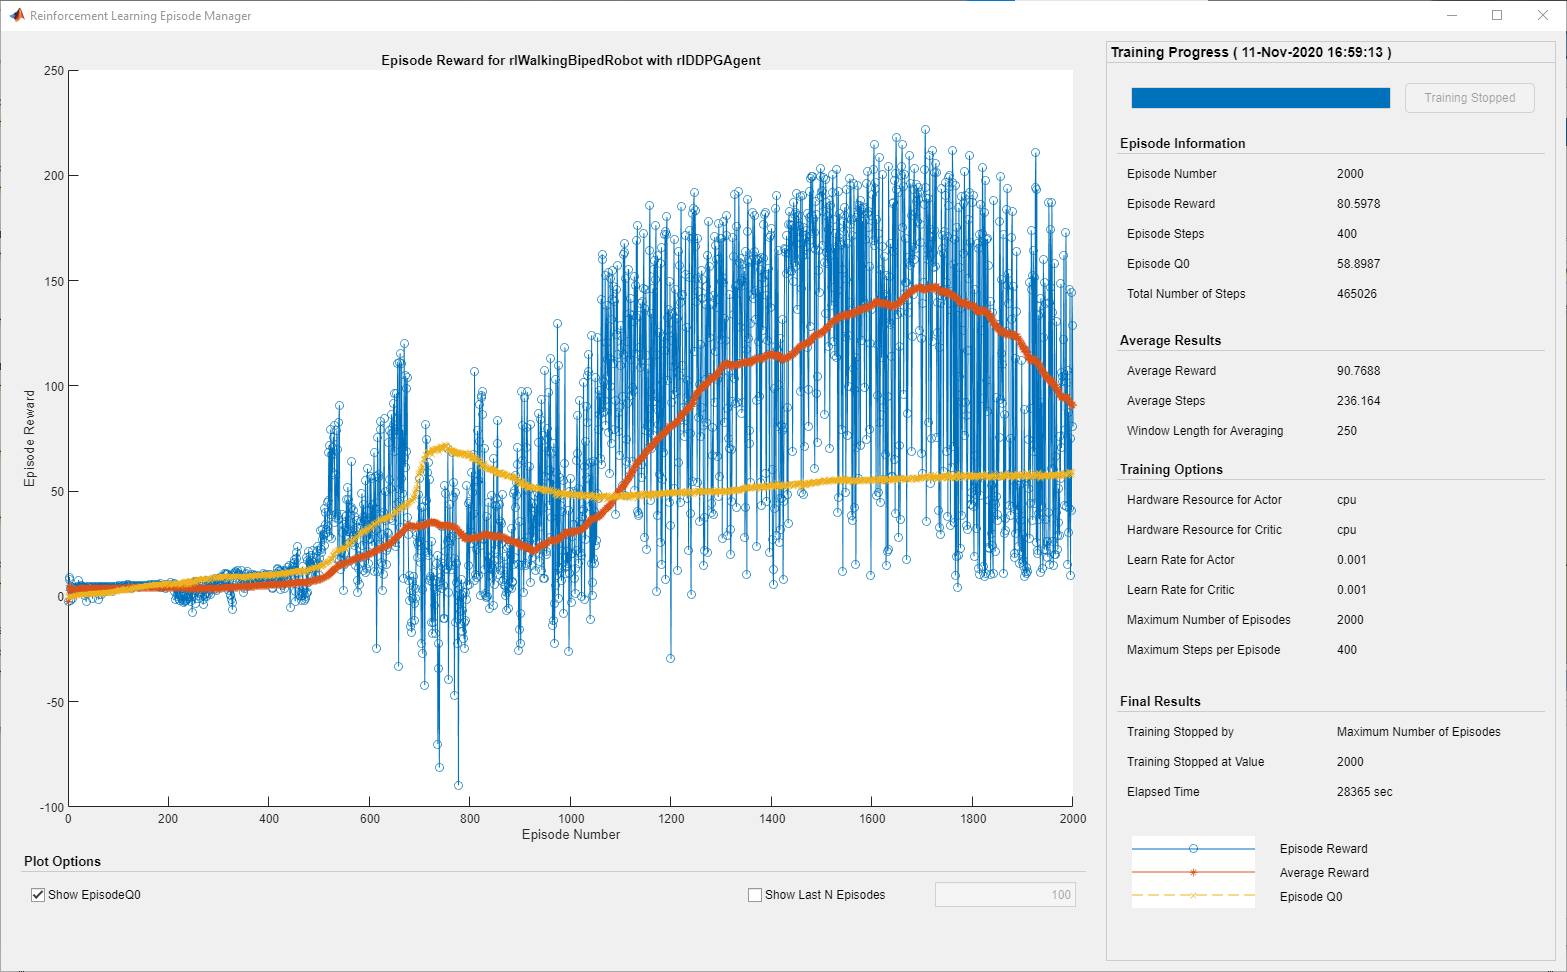

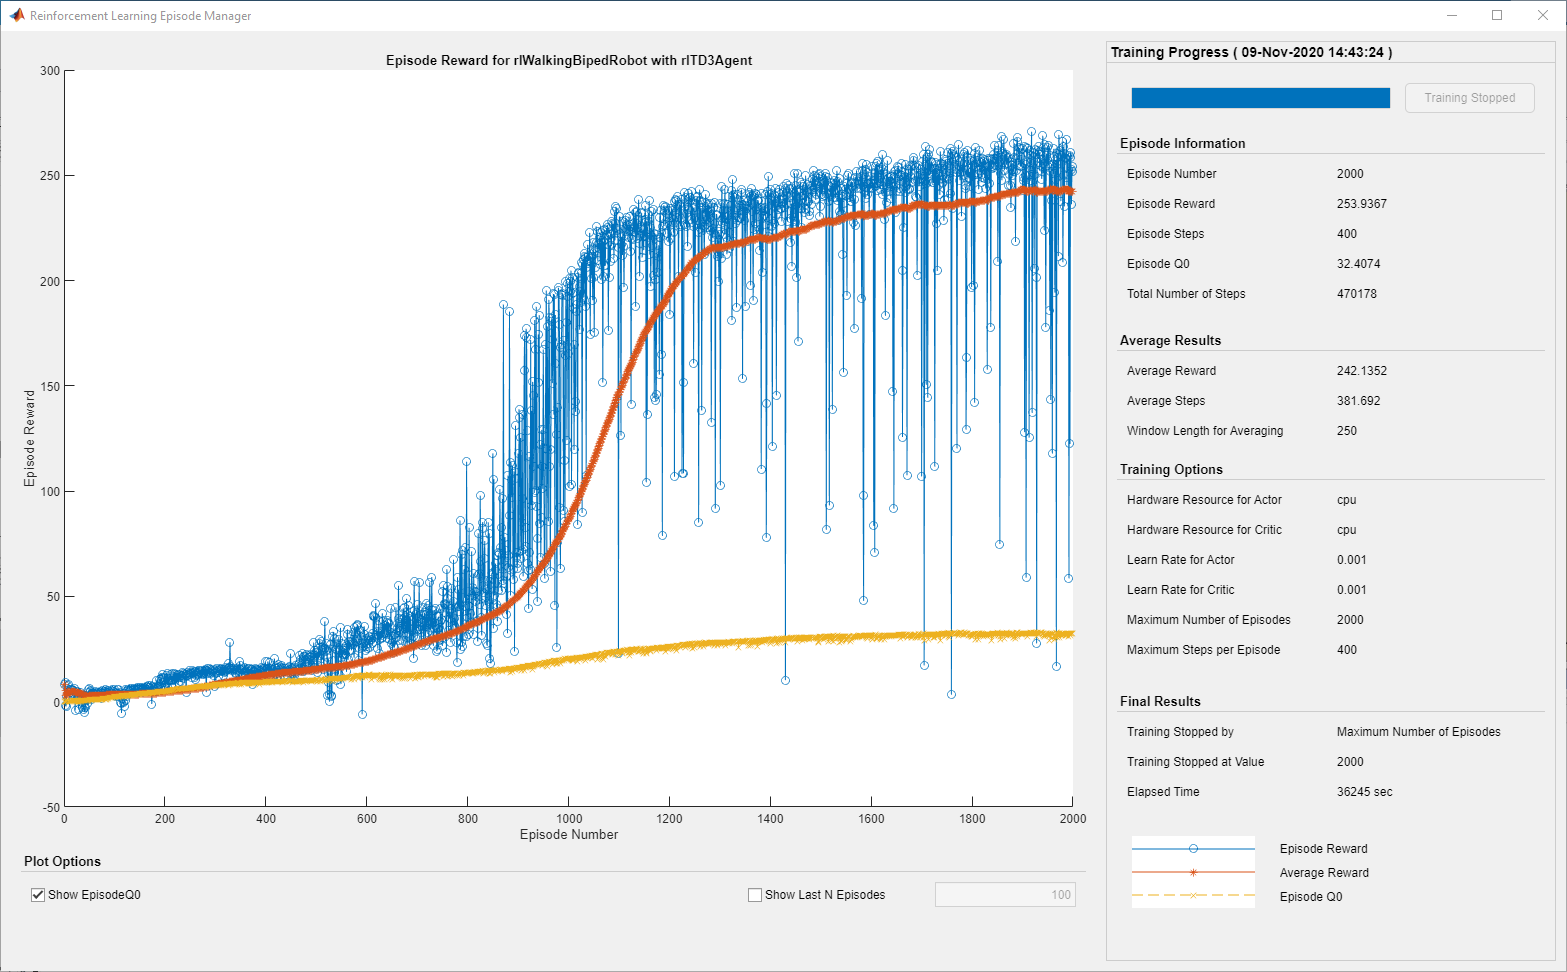

For the preceding example training curves, the average time per training step for the DDPG and TD3 agents are 0.11 and 0.12 seconds, respectively. The TD3 agent takes more training time per step because it updates two critic networks compared to the single critic used for DDPG. 

## Simulate Trained Agents

Fix the random generator seed for reproducibility.

rng(0)

To validate the performance of the trained agent, simulate it within the biped robot environment. For more information on agent simulation, see [`rlSimulationOptions`](docid:rl_ref#mw_983bb2e9-0115-4548-8daa-687037e090b2) and [`sim`](docid:rl_ref#mw_e6296379-23b5-4819-a13b-210681e153bf).

simOptions = rlSimulationOptions(MaxSteps=maxSteps);
experience = sim(env,agent,simOptions);

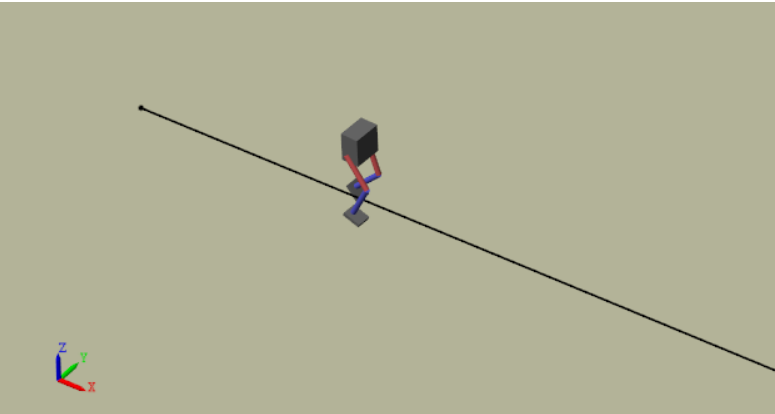

## Compare Agent Performance

For the following agent comparison, each agent was trained five times using a different random seed each time. Due to the random exploration noise and the randomness in the parallel training, the learning curve for each run is different. Since the training of agents for multiple runs takes several days to complete, this comparison uses pretrained agents.

For the DDPG and TD3 agents, plot the average and standard deviation of the episode reward (top plot) and the episode Q0 value (bottom plot). The episode Q0 value is the critic estimate of the discounted long-term reward at the start of each episode given the initial observation of the environment. For a well-designed critic, the episode Q0 value approaches the true discounted long-term reward.

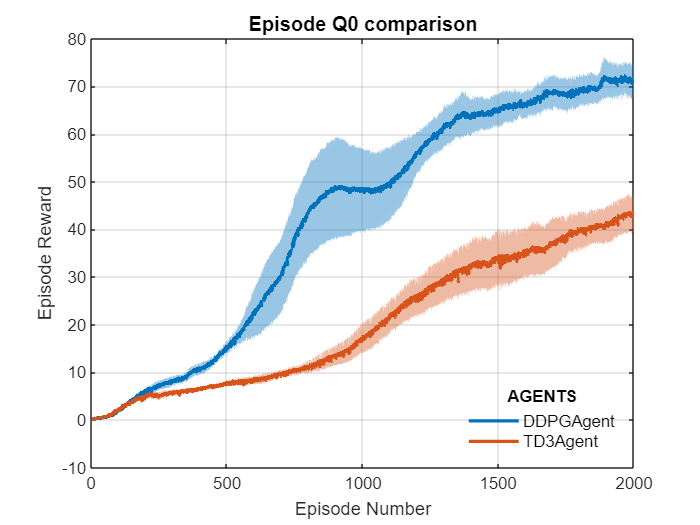

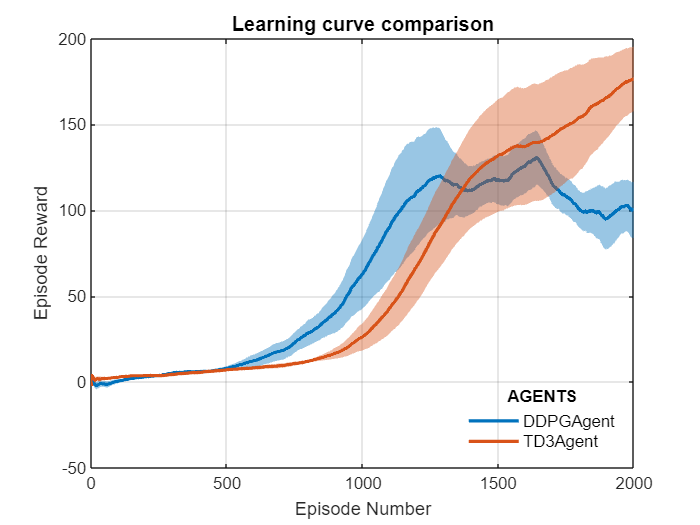

comparePerformance("DDPGAgent","TD3Agent")

Based on the Learning curve comparison plot:

- The DDPG agent appears to pick up learning faster (around episode number 600 on average) but hits a local minimum. TD3 starts slower but eventually achieves higher rewards than DDPG as it avoids overestimation of Q values.

- The TD3 agent shows a steady improvement in its learning curve, which suggests improved stability when compared to the DDPG agent. 

Based on the Episode Q0 comparison plot:

- For the TD3 agent, the critic estimate of the discounted long-term reward (for 2000 episodes) is lower compared to the DDPG agent. This difference is because the TD3 algorithm takes a conservative approach in updating its targets by using a minimum of two Q functions. This behavior is further enhanced because of delayed updates to the targets.

- Although the TD3 estimate for these 2000 episodes is low, the TD3 agent shows a steady increase in the episode Q0 values, unlike the DDPG agent.

In this example, the training was stopped at 2000 episodes. For a larger training period, the TD3 agent with its steady increase in estimates shows the potential to converge to the true discounted long-term reward.

For another example on how to train a humanoid robot to walk using a DDPG agent, see [Train a Humanoid Walker](docid:sm_ug#example-sm_humanoid_walker). For an example on how to train a quadruped robot to walk using a DDPG agent, see [Quadruped Robot Locomotion Using DDPG Agent](docid:rl_ug#mw_e8e349f7-8877-420a-9e5c-a21151d0bccb).

## References

[1] Lillicrap, Timothy P., Jonathan J. Hunt, Alexander Pritzel, Nicolas Heess, Tom Erez, Yuval Tassa, David Silver, and Daan Wierstra. "Continuous Control with Deep Reinforcement Learning." Preprint, submitted July 5, 2019. [https://arxiv.org/abs/1509.02971](https://arxiv.org/abs/1509.02971).

[2] Heess, Nicolas, Dhruva TB, Srinivasan Sriram, Jay Lemmon, Josh Merel, Greg Wayne, Yuval Tassa, et al. "Emergence of Locomotion Behaviours in Rich Environments." Preprint, submitted July 10, 2017. [https://arxiv.org/abs/1707.02286](https://arxiv.org/abs/1707.02286).

[3] Fujimoto, Scott, Herke van Hoof, and David Meger. "Addressing Function Approximation Error in Actor-Critic Methods." Preprint, submitted October 22, 2018. [https://arxiv.org/abs/1802.09477](https://arxiv.org/abs/1802.09477).

*Copyright 2019 The MathWorks, Inc.*